**COT 5930 Image processing, spring 2021  -- Christian Garbin**

# Assignment 5: Image classification

Code in this live script was created based on the starter code. All unattributed text and code should be assumed to be from the starter code. All  mistakes an dpoorly written pieces of code are mine.

All experriments use a subset of Kaggle's "dogs vs. cats" trainign dataset (https://www.kaggle.com/c/dogs-vs-cats/data?select=train.zip).

Experiments are titled as follows:

- Base network name (all networks are customized for transfer learning)

- Test/validation partition

- Optimizer

- Data augmentation (yes/no)

For example, "AlexNet, 70/30, sgdm, no augmenation" is an experiment that uses AlexNet with transfer leraning, 70% of the dataset is used for training (and 30% for validation), with the SGDM optimizer, and no data augmentation.

## Experiment 1 - AlexNet, 70/30, sgdm, no agumentation

Create the dataset.

[trainingSet1, validationSet1] = getDataset(0.7,'AlexNet');

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=14, dog=14
Validation set distribution: cat=6, dog=6


Create the model.

model1 = alexNextTransferLearning();

Train the model.

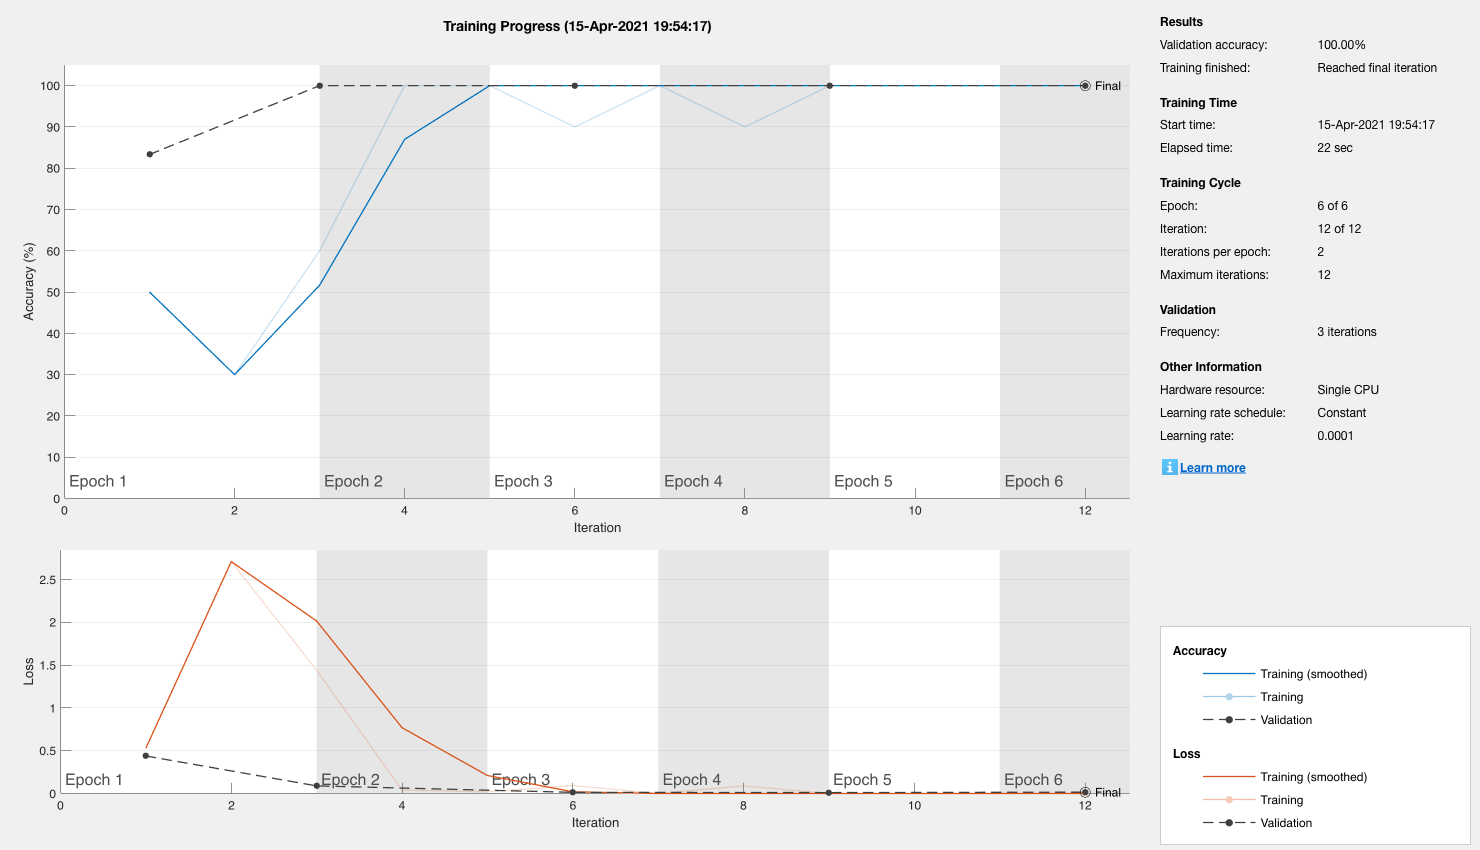

options1 = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet1, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

[YPred1,scores1] = trainEvaluate(model1,options1,trainingSet1,validationSet1);

Accuracy and confusion matrix.

12 of 12 images were predicted correctly
The validation accuracy is: 100.00 %

Confusion matrix


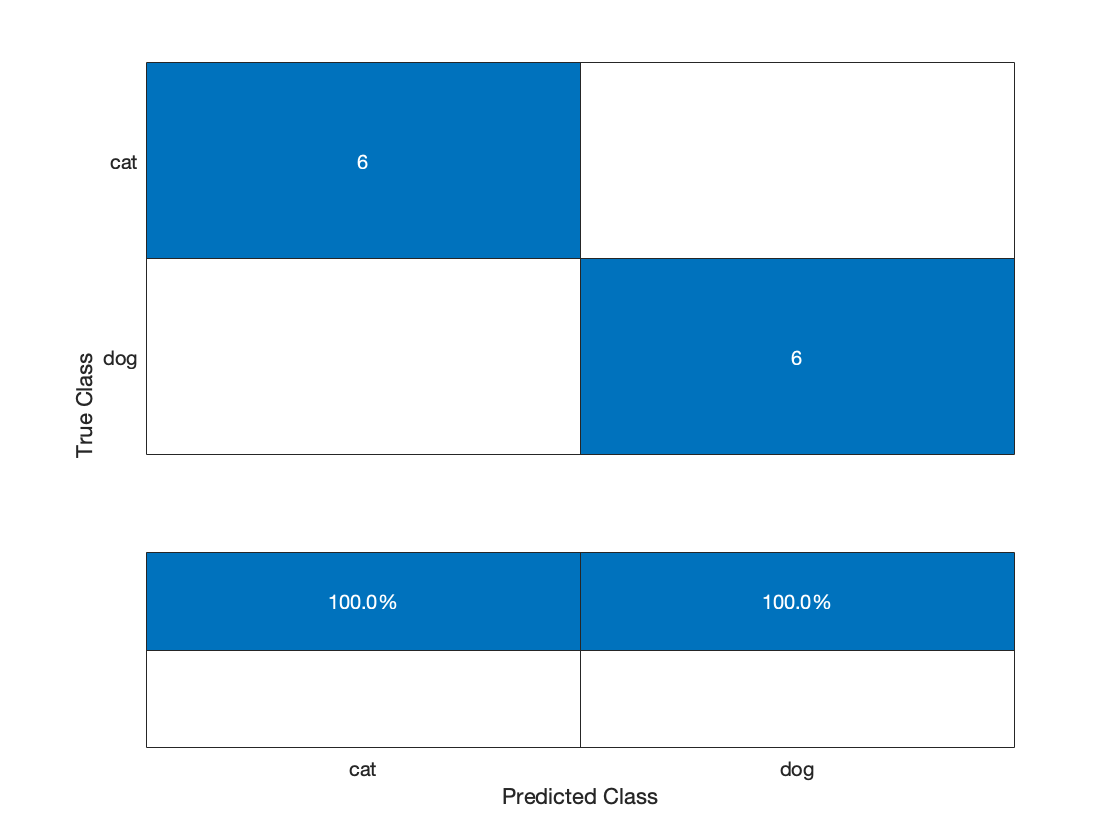

showPredictionResults(validationSet1, YPred1)

Some correctly predicted images.

Correct predictions
Prediction: cat, scores: cat=0.999914, dog=0.000086


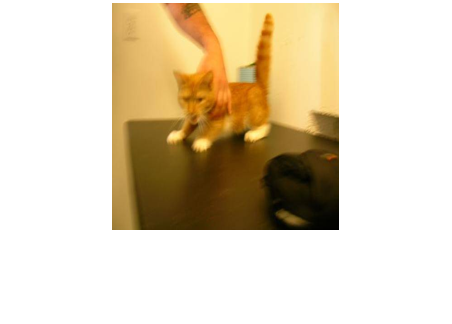

Prediction: cat, scores: cat=1.000000, dog=0.000000


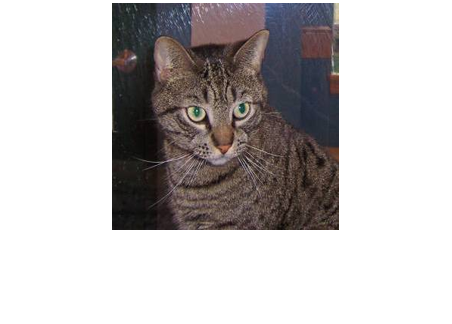

Prediction: cat, scores: cat=1.000000, dog=0.000000


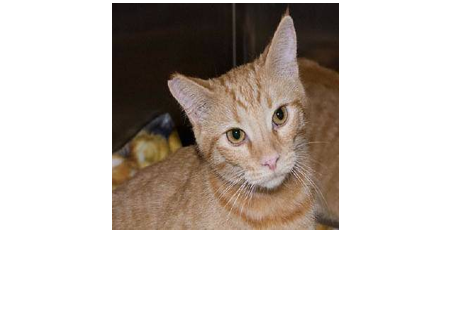

Prediction: cat, scores: cat=0.999962, dog=0.000038


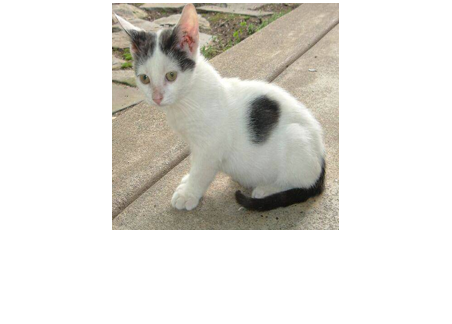

Prediction: cat, scores: cat=1.000000, dog=0.000000


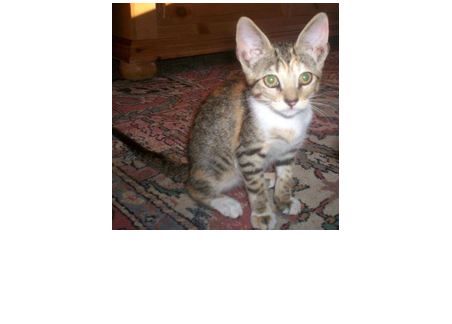

showImages(validationSet1, YPred1, scores1, true)

Some incorrectly predicted images.

showImages(validationSet1, YPred1, scores1, false)

Incorrect predictions


## Experiment 2 - AlexNet, 80/20, sgdm, no agumentation

Create the dataset.

[trainingSet2, validationSet2] = getDataset(0.8,'AlexNet');

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=16, dog=16
Validation set distribution: cat=4, dog=4


Create the model.

model2 = alexNextTransferLearning();

Train the model.

**NOTE** that we are using the same training options from the first experiment.

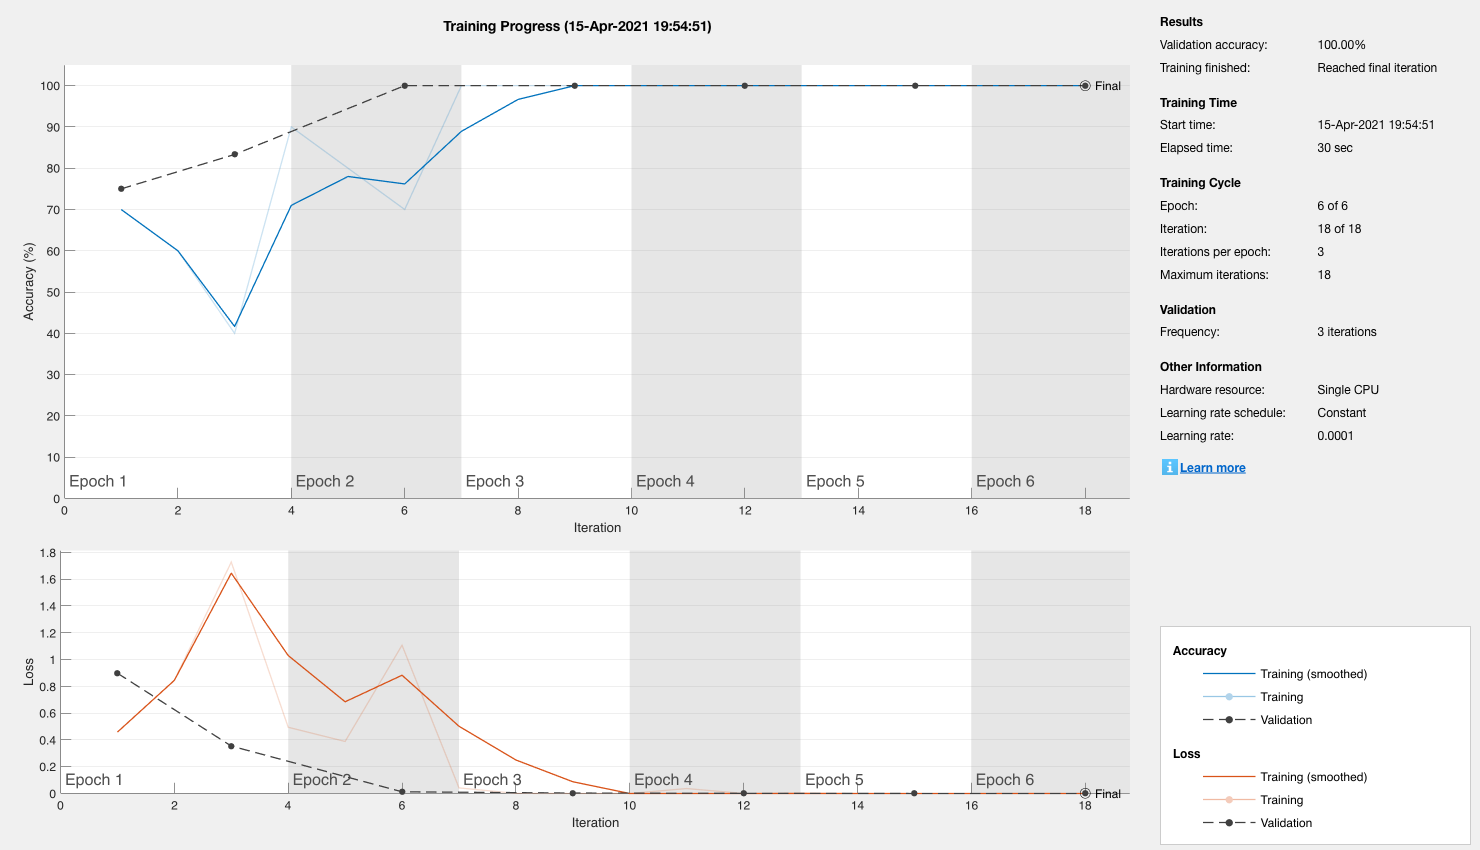

[YPred2,scores2] = trainEvaluate(model2,options1,trainingSet2,validationSet2);

Accuracy and confusion matrix.

8 of 8 images were predicted correctly
The validation accuracy is: 100.00 %

Confusion matrix


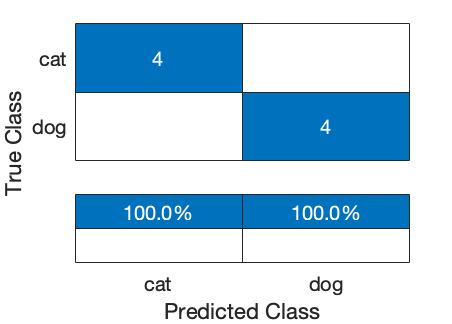

showPredictionResults(validationSet2, YPred2)

Some correctly predicted images.

Correct predictions
Prediction: cat, scores: cat=1.000000, dog=0.000000


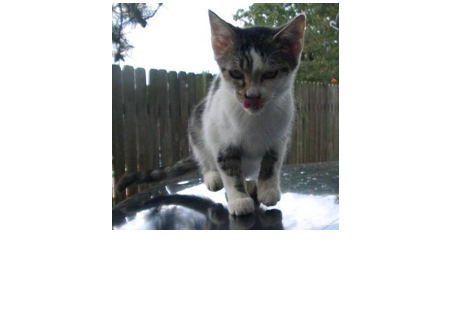

Prediction: cat, scores: cat=1.000000, dog=0.000000


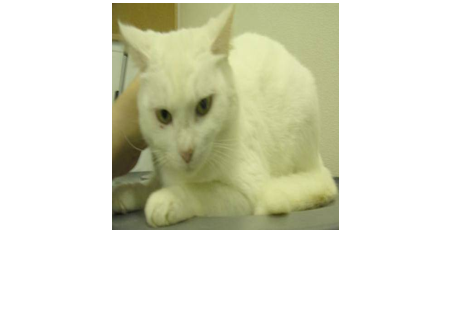

Prediction: cat, scores: cat=1.000000, dog=0.000000


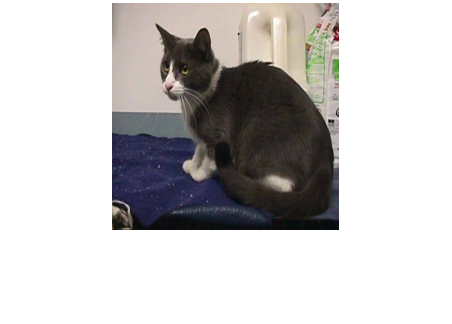

Prediction: cat, scores: cat=1.000000, dog=0.000000


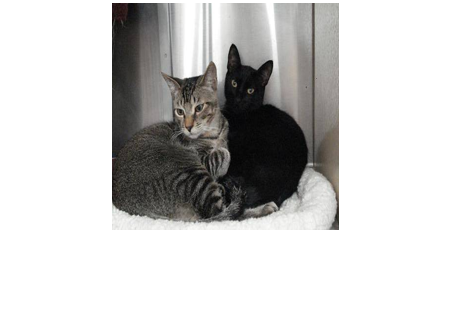

Prediction: dog, scores: cat=0.000000, dog=1.000000


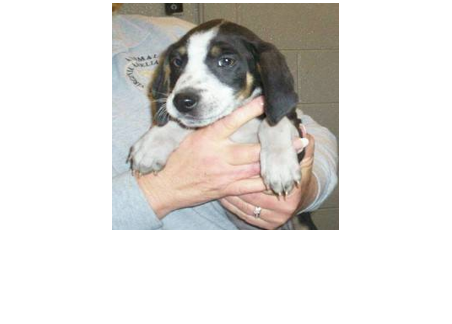

showImages(validationSet2, YPred2, scores2, true)

Some incorrectly predicted images.

showImages(validationSet2, YPred2, scores2, false)

Incorrect predictions


## Experiment 3 - AlexNet, 80/20, rmsprop, no agumentation

Create the dataset.

[trainingSet3, validationSet3] = getDataset(0.8,'AlexNet');

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=16, dog=16
Validation set distribution: cat=4, dog=4


Create the model.

model3 = alexNextTransferLearning();

Train the model.

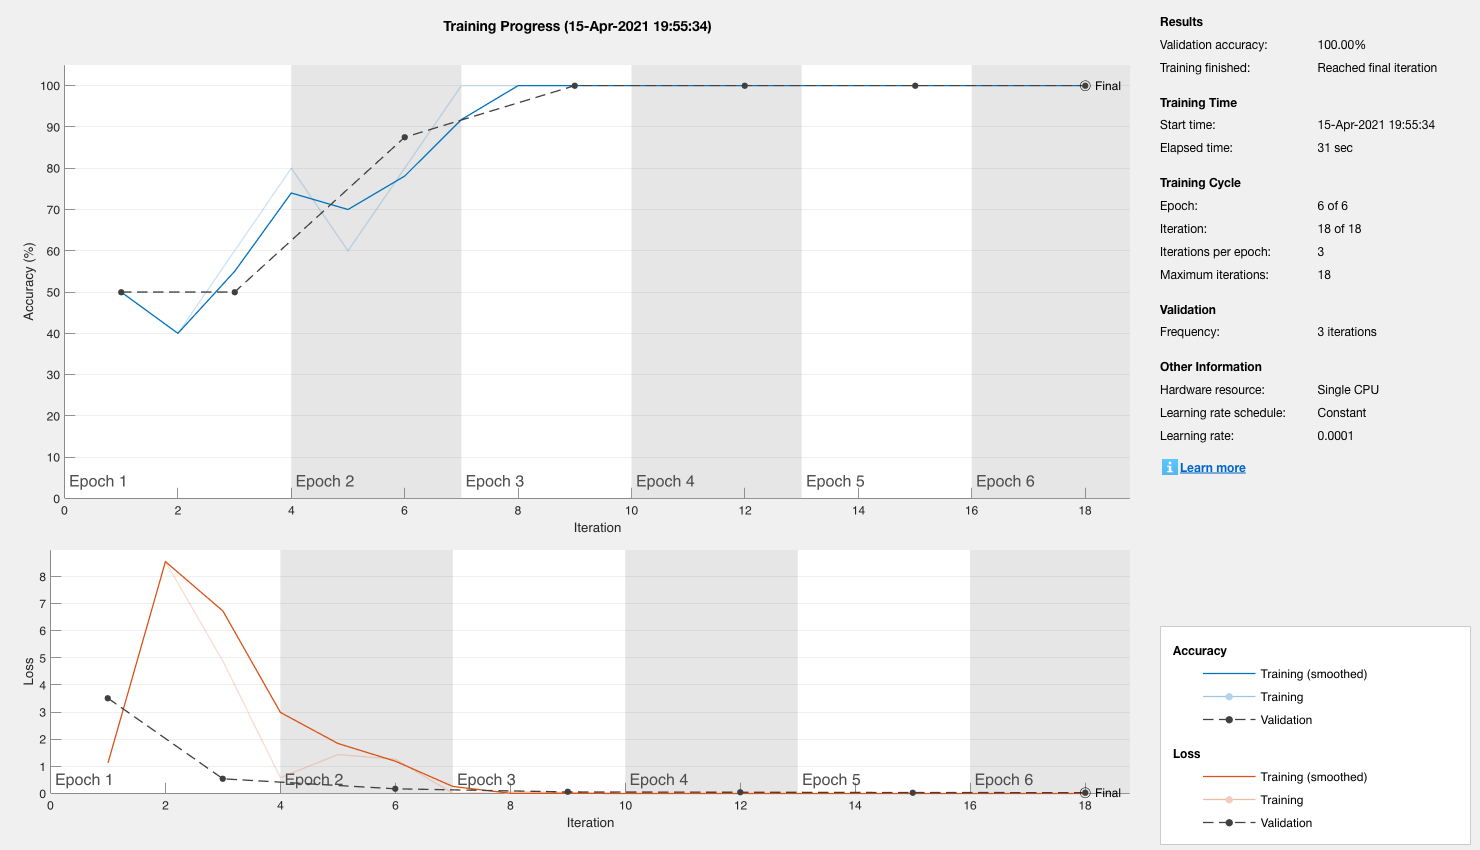

options3 = trainingOptions('rmsprop', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet3, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

[YPred3,scores3] = trainEvaluate(model3,options3,trainingSet3,validationSet3);

Accuracy and confusion matrix.

8 of 8 images were predicted correctly
The validation accuracy is: 100.00 %

Confusion matrix


showPredictionResults(validationSet3, YPred3)

Some correctly predicted images.

Correct predictions
Prediction: cat, scores: cat=0.890849, dog=0.109151


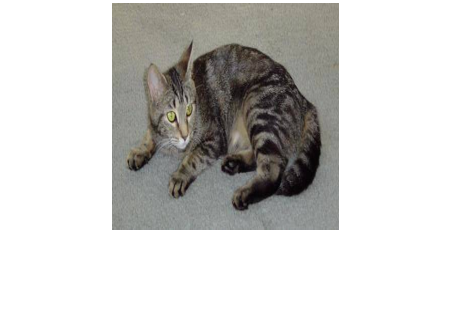

Prediction: cat, scores: cat=0.959470, dog=0.040530


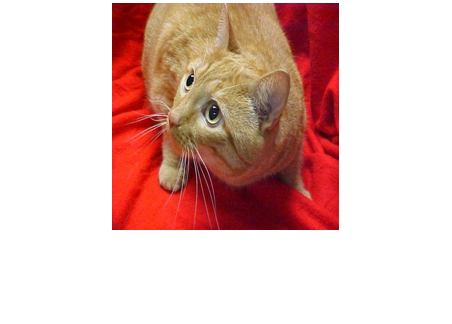

Prediction: cat, scores: cat=0.998666, dog=0.001334


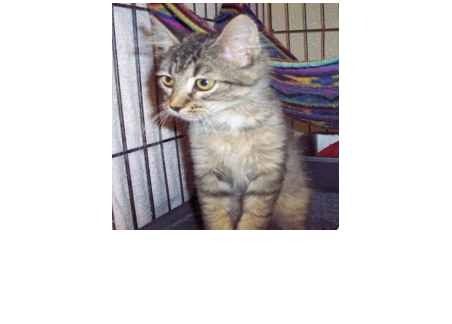

Prediction: cat, scores: cat=0.999988, dog=0.000012


Prediction: dog, scores: cat=0.000047, dog=0.999953


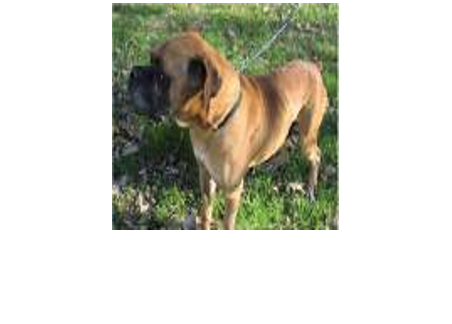

showImages(validationSet3, YPred3, scores3, true)

Some incorrectly predicted images.

showImages(validationSet3, YPred3, scores3, false)

Incorrect predictions


## Experiment 4 - GoogleLeNet, 80/20, rmsprop, no agumentation

Create the dataset.

[trainingSet4, validationSet4] = getDataset(0.8,'GoogleLeNet');

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=16, dog=16
Validation set distribution: cat=4, dog=4


Create the model.

model4 = googleLeNetTansferLearning();

Train the model.

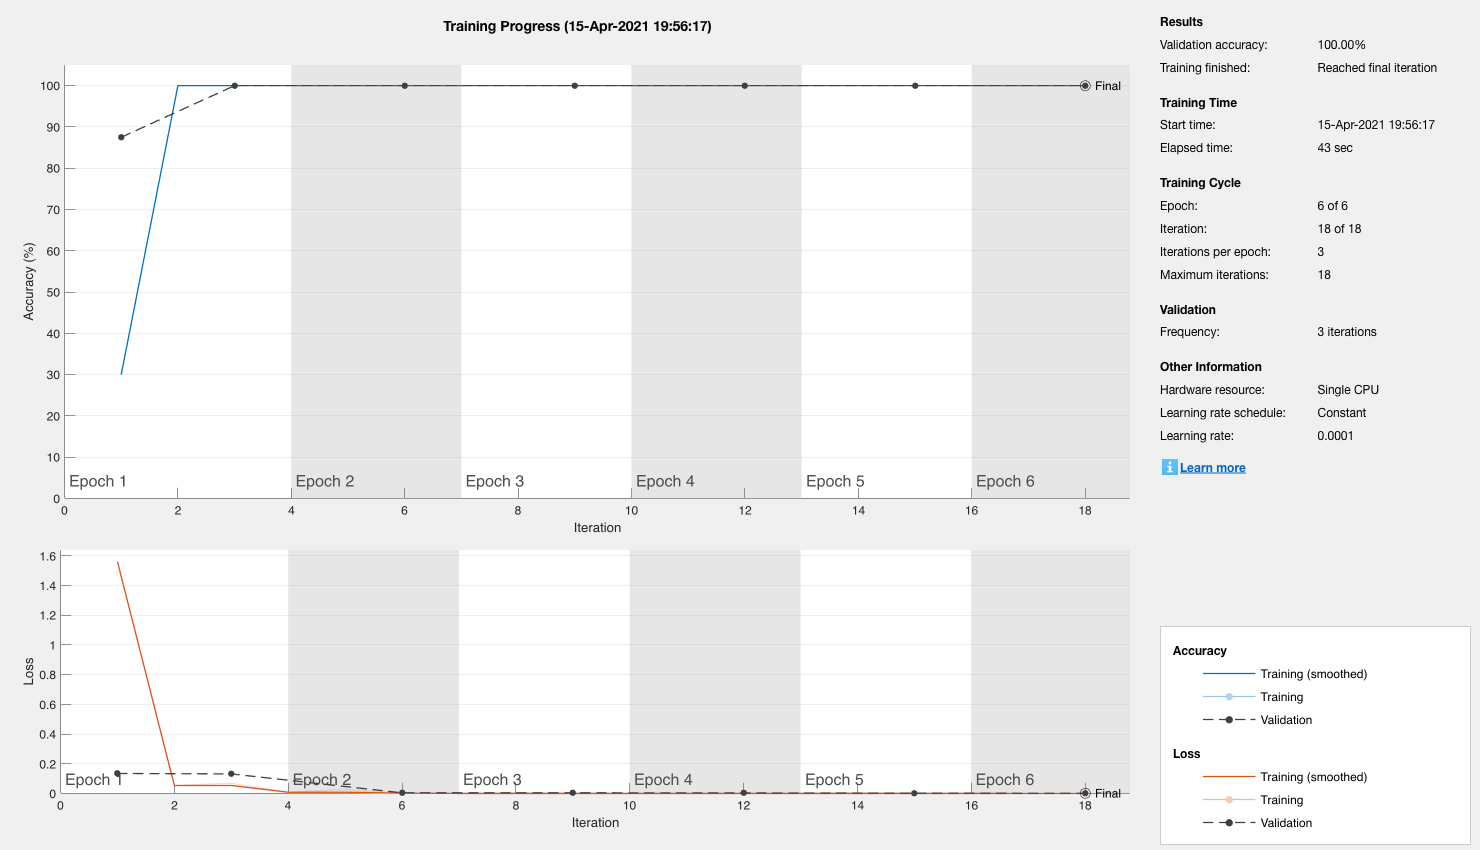

options4 = trainingOptions('rmsprop', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',validationSet4, ...
    'ValidationFrequency',3, ...
    'ValidationPatience',Inf, ...
    'Verbose',false ,...
    'Plots','training-progress');

[YPred4,scores4] = trainEvaluate(model4,options4,trainingSet4,validationSet4);

Accuracy and confusion matrix.

8 of 8 images were predicted correctly
The validation accuracy is: 100.00 %

Confusion matrix


showPredictionResults(validationSet4, YPred4)

Some correctly predicted images.

Correct predictions
Prediction: cat, scores: cat=0.999992, dog=0.000008


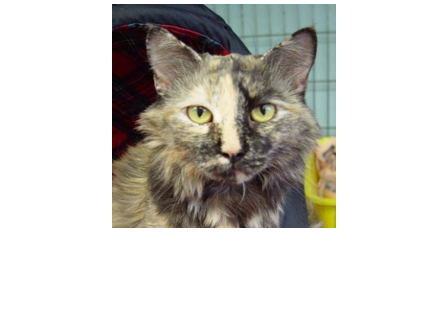

Prediction: cat, scores: cat=0.998547, dog=0.001453


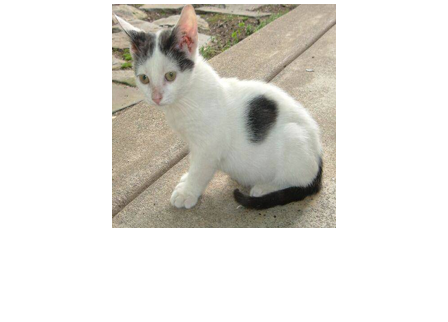

Prediction: cat, scores: cat=0.999994, dog=0.000006


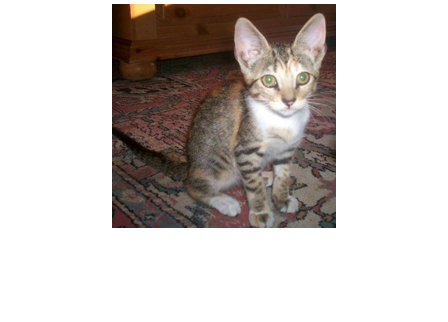

Prediction: cat, scores: cat=0.992048, dog=0.007952


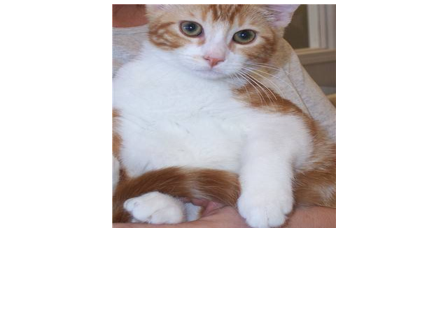

Prediction: dog, scores: cat=0.000039, dog=0.999961


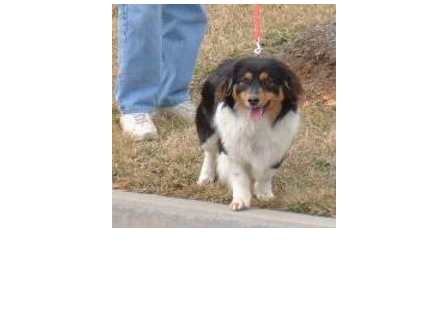

showImages(validationSet4, YPred4, scores4, true)

Some incorrectly predicted images.

showImages(validationSet4, YPred4, scores4, false)

Incorrect predictions


## Experiment 5 - GoogleLeNet, 80/20, rmsprop, with augmentation

Create the model.

model5 = googleLeNetTansferLearning();

Create an augmented dataset.

[trainingSet5, validationSet5] = getDataset(0.8,'GoogleLeNet');

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=16, dog=16
Validation set distribution: cat=4, dog=4



% In our case, we shall use an augmented image datastore to randomly flip
% the training images along the vertical axis and randomly translate them
% up to 30 pixels and scale them up to 10% horizontally and vertically.
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

inputSize = model5.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet5, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet5);

Train the model.

miniBatchSize = 10;
options5 = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

trainedModel5 = trainNetwork(augimdsTrain,model5,options5);

Predict scores on the validation set and calculate accuracy.

[YPredAug5,probsAug5] = classify(trainedModel5,augimdsValidation);

Accuracy and confusion matrix.

8 of 8 images were predicted correctly
The validation accuracy is: 100.00 %

Confusion matrix


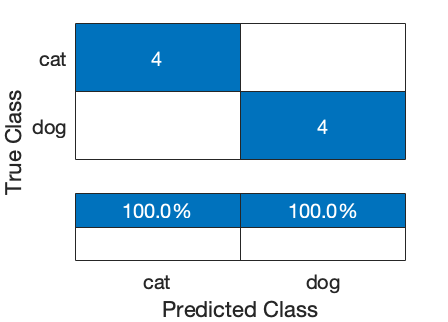

showPredictionResults(validationSet4, YPred4)

Some correctly predicted images.

Correct predictions
Prediction: cat, scores: cat=0.999992, dog=0.000008


Prediction: cat, scores: cat=0.998547, dog=0.001453


Prediction: cat, scores: cat=0.999994, dog=0.000006


Prediction: cat, scores: cat=0.992048, dog=0.007952


Prediction: dog, scores: cat=0.000039, dog=0.999961


showImages(validationSet4, YPred4, scores4, true)

## Data augmentation

imageAugmentation object.

will fail here

Unrecognized function or variable 'will'.


% In our case, we shall use an augmented image datastore to randomly flip
% the training images along the vertical axis and randomly translate them
% up to 30 pixels and scale them up to 10% horizontally and vertically.
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

Augmented training and validation sets.

inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations)

augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations)

## Retrain with augmented data

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

modelAug = trainNetwork(augimdsTrain,layers,options);

Predict scores on the validation set and calculate accuracy.

[YPredAug,probsAug] = classify(modelAug,augimdsValidation);

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

# Auxiliary functions

### Dataset

Create a dataset backed by an image store. The function assumes there are only two categories and that the directory structure is correctly split into these categories (the name of the directories mus match the name of the categories for the `imageDatastore` to work correctly).

function [trainingSet, validationSet] = getDataset(trainPercentage, network)

    CATEGORIES = {'cat', 'dog'};
    PATH = './data/PetImages';

    function showStats(text, imds)
        tempTbl = countEachLabel(imds);
        fprintf("%s: %s=%d, %s=%d\n", text, ...
            tempTbl(1,1).Label, tempTbl(1,2).Count, ...
            tempTbl(2,1).Label, tempTbl(2,2).Count)
    end

    imds = imageDatastore(fullfile(PATH, CATEGORIES), 'LabelSource', 'foldernames');
    showStats('Dataset distribution before rebalancing', imds)
   
    % Ensure the categories are balanced by using the smallest overlap set (may not be
    % needed for some datasets, but protects in case we use an unbalanced dataset
    % without realizing it).
    tbl = countEachLabel(imds);
    minSetCount = min(tbl{:,2});
    % Trim the set.
    imds = splitEachLabel(imds, minSetCount, 'randomize');
    % Each set must now have exactly the same number of images.
    showStats('Dataset distribution after rebalancing', imds)
    
    % AlexNet can only process RGB images that are 227-by-227
    % To avoid re-saving all the images to this format, setup the |imds| read function,
    % |imds.ReadFcn|, to pre-process images on-the-fly. The |imds.ReadFcn| is called
    % every time an image is read from the |ImageDatastore|
    if isequal(network,'AlexNet')
        imds.ReadFcn = @(filename)readAndPreprocessImageAlexNet(filename);
    else
        imds.ReadFcn = @(filename)readAndPreprocessImageGoogleLeNet(filename);
    end
    
    [trainingSet, validationSet] = splitEachLabel(imds, trainPercentage, 'randomized');
    showStats('Training set distribution', trainingSet)
    showStats('Validation set distribution', validationSet)
end

### Model

Create an AlexNet model ready for transfer learning.

function model = alexNextTransferLearning()
    originalModel = alexnet;
    
    layersTransfer = originalModel.Layers(1:end-3);

    NUM_CLASSES = 2;
    
    model = [
        layersTransfer
        fullyConnectedLayer(NUM_CLASSES,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
        softmaxLayer
        classificationLayer];
end

Create a GoogleLeNet model ready for transfer learning. Based on [https://www.mathworks.com/help/releases/R2018a/nnet/examples/transfer-learning-using-googlenet.html.](https://www.mathworks.com/help/releases/R2018a/nnet/examples/transfer-learning-using-googlenet.html.) 

function model = googleLeNetTansferLearning()
    originalModel = googlenet;

    lgraph = layerGraph(originalModel);
    lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});

    NUM_CLASSES = 2;
    
    newLayers = [
        fullyConnectedLayer(NUM_CLASSES,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
        softmaxLayer('Name','softmax')
        classificationLayer('Name','classoutput')];
    lgraph = addLayers(lgraph,newLayers);
        
    model = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');
end

Train an evaluate a model.

function [YPred,scores] = trainEvaluate(model,options,trainingSet,validationSet)
    trainedModel = trainNetwork(trainingSet,model,options);    
    [YPred,scores] = classify(trainedModel,validationSet);
end

Show the prediction results.

function showPredictionResults(validationSet, YPredicted)
    YValidation = validationSet.Labels;

    correct = YPredicted == YValidation;
    fprintf("\n\n%d of %d images were predicted correctly\n", ...
        sum(correct), numel(YValidation));
    fprintf("The validation accuracy is: %.2f %%\n",mean(correct) * 100);

    fprintf("\nConfusion matrix\n")
    confusionchart(YValidation,YPredicted, ...
        "ColumnSummary","column-normalized")
end

Show correctly/incorrectly images.

function showImages(validationSet, YPredicted, scores, showCorrect)
    if showCorrect
       fprintf("Correct predictions\n")
    else    
       fprintf("Incorrect predictions\n")
    end

    NUM_IMAGES = 5;
    YValidation = validationSet.Labels;

    shownImages = 0;
    for i = 1:numel(YValidation)
        if showCorrect
            show = (YValidation(i) == YPredicted(i));
        else
            show = (YValidation(i) ~= YPredicted(i));
        end
        
        if show
            shownImages = shownImages + 1;
            if shownImages > NUM_IMAGES
                break
            end

            fprintf("Prediction: %s, scores: cat=%f, dog=%f\n", ...
                YPredicted(i), scores(i,1), scores(i,2))
            figure
            img = readimage(validationSet,i);
            imshow(img)
            drawnow
        end
    end
end